load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
addpath('funcs');
% lateralSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-disagree, 1-agree
% orderSheet= zeros(Delta_e_steps, Delta_i_steps); % -1-NaN, 0-disagree, 1-agree
% gammaSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-noGamma, XX-frequency
% betaSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-noBeta, XX-frequency
% ratioSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, X-ratio
% osciSheet = zeros(Delta_e_steps, Delta_i_steps,5,2); % -1-NaN, 0-noOsci, 1-hasOsci; before and after

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 100;

Iattn = 0.02;

n = 1:100;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 18;
steps = size(orderSheet,1);

## Agree with lateral AND order

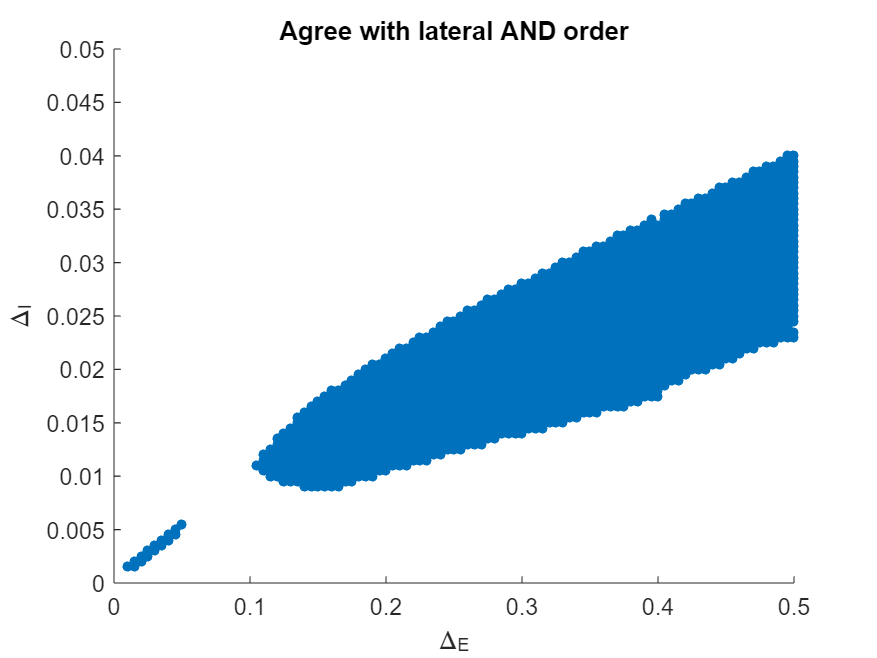

lat = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0
            lat(i,j) = 1;
        end
    end
end

roi = orderSheet & lat == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz,'filled',"MarkerFaceColor","#0072BD");
    hold on
end
xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Agree with lateral AND order");

## Agree with lateral OR order

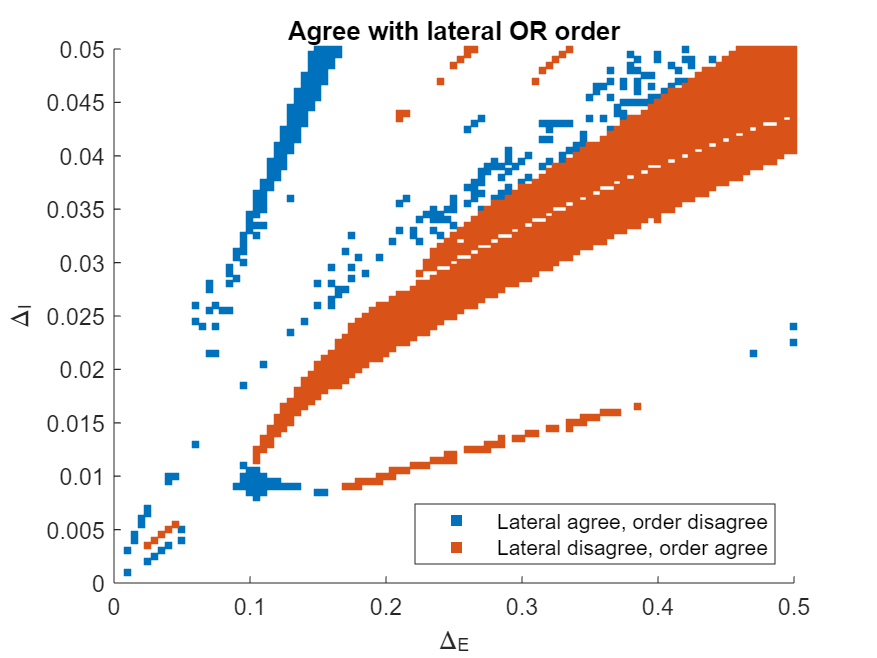

% lateral agree, order disagree (LaOd)
lat = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0
            lat(i,j) = 1;
        end
    end
end

LaOd = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lat(i,j) == 1 && orderSheet(i,j) == 0
            LaOd(i,j) = 1;
        end
    end
end
% lateral disagree, order agree (LdOa)
LdOa = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lat(i,j) == 0 && orderSheet(i,j) == 1
            LdOa(i,j) = 1;
        end
    end
end

figure();
roi = LaOd == 1;
sz = 18;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'square','filled',"MarkerFaceColor","#0072BD");
    hold on
end

roi = LdOa == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'square','filled',"MarkerFaceColor","#D95319");
    hold on
end

xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Lateral agree, order disagree","Lateral disagree, order agree"], ...
    "Location","southeast");
title("Agree with lateral OR order");

## Order agree, but...

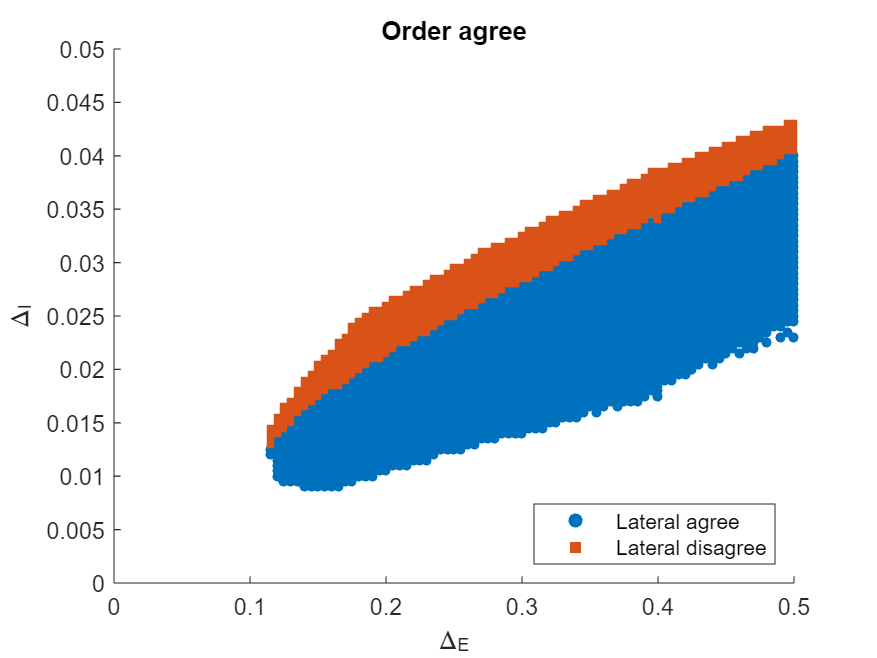

roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0 && orderSheet(i,j) == 1 && sum(gammaSheet(i,j,:)>0)==5 && sum(betaSheet(i,j,:)>0)==0
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;

figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'filled',"MarkerFaceColor","#0072BD");
    hold on
end
xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Agree with lateral AND order");

% lateral disagree, order agree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)==1) == 3 && orderSheet(i,j) == 1 && sum(gammaSheet(i,j,:)>0)==5 && sum(betaSheet(i,j,:)>0)==0
            roi(i,j) = 1;
        end
    end
end


roi = roi == 1;
% remove some points
roi(1,52:53) = 0; roi(2,52) = 0; roi(3,51) = 0; roi(4,50) = 0; roi(7,48) = 0;

% plot
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'square','filled',"MarkerFaceColor","#D95319");
end

xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Order agree");
legend([s1 s2],["Lateral agree","Lateral disagree"], ...
    "Location","southeast");

## oscillatory region

% is there 
load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
osci = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(osciSheet(i,j,2,:)==1)==5
            osci(i,j) = 1;
        end
    end
end
roi = osci == 1;
figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz,'square','filled',"MarkerFaceColor","#0072BD");
    hold on
end
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Oscillation: After ON");


## Ratio

load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
down = 0.25; up = 2;
roi = ratioSheet > down & ratioSheet < up;
figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz,'square','filled',"MarkerFaceColor","#0072BD");
    hold on
end
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Ratio between "+num2str(down)+" and "+num2str(up));


## Why LaOd? PET

% PET
Delta_e = 0.14; Delta_i = 0.045; Iattn = 0.02; allTime = 10000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
strt_prd = 300000; end_prd = 1000000;
PET = getPET(v(:,strt_prd:end_prd,:),g(:,:,strt_prd:end_prd,:));


## EXC-INH

exc = squeeze(PET(5,1,:));% + squeeze(PET(5,3,:)) + ...
    % squeeze(PET(5,5,:)) + squeeze(PET(5,7,:));
inh = squeeze(PET(5,2,:));% + squeeze(PET(5,4,:)) + ...
    % squeeze(PET(5,6,:)) + squeeze(PET(5,8,:));

y = [exc-inh];
figure();
bar(y);
ylim([27.5 28.5]);
xticklabels(["Cond1", "Cond2", "Cond3", "Cond4", "Cond5"]);
ylabel("Energy Transmission");
% legend("exc","inh","Location","southeast");


## Why LdOa? PET

% PET
Delta_e = 0.11; Delta_i = 0.013; Iattn = 0.02; allTime = 10000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
strt_prd = 300000; end_prd = 1000000;
PET = getPET(v(:,strt_prd:end_prd,:),g(:,:,strt_prd:end_prd,:));

## Lateral

y = [];
for i = 1:5
    oneTwo = squeeze(PET(10,1,i));
    twoOne = squeeze(PET(2,9,i));
    y = [y;oneTwo twoOne];
end
figure();
bar(y);
% ylim([3 3.5]);
xticklabels(["Cond1", "Cond2", "Cond3", "Cond4", "Cond5"]);
ylabel("Energy Transmission in lateral pathway");
legend("C1 to C2","C2 to C1",'Location','southeast');
title("Lateral pathway");

## 1L5E and 2L5E

pops = {'1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i', ...
    '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'};
pop1 = 1; pop2 = 2; pop3 = 5; pop4 = 6;
c1s = [squeeze(PET(pop1,5,4)); squeeze(PET(5,pop1,4)); squeeze(PET(5,pop2,4));...
    squeeze(PET(5,pop3,4)); squeeze(PET(5,pop4,4))];
c2s = [squeeze(PET(pop1+8,13,4)); squeeze(PET(13,pop1+8,4)); squeeze(PET(13,pop2+8,4));...
    squeeze(PET(13,pop3+8,4)); squeeze(PET(13,pop4+8,4))];
y = [c1s c2s];
figure();
bar(y);
% ylim([25 30]);
xticklabels(["L5E to L2/3E", "L2/3E to L5E", "L2/3I to L5E", "L5E to L5E", "L5I to L5E"]);
title("1L5E and 2L5E");
legend("C1","C2","Location","southeast");


## PET

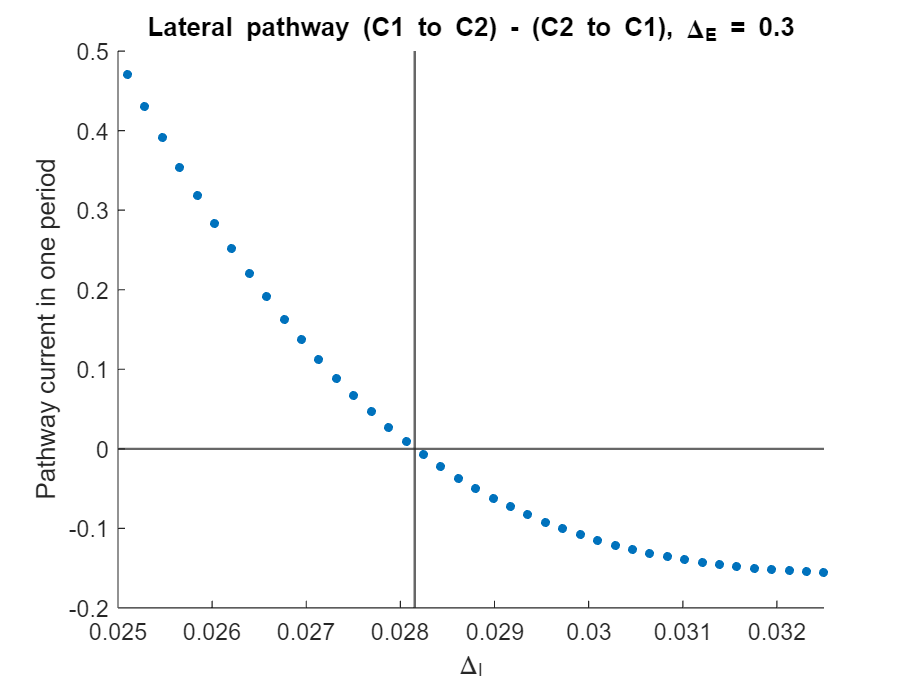

load lateral\lateral_PET_0.3_0.3_0.014_0.0325_Iattn_0.02.mat
startX = 0.014; endX = 0.0325; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,z,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
% s2 = scatter(x,y2,sz,"filled",'MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',1);
yline(0,'LineWidth',1);

xlim([0.025 endX]);
% set(gca, 'YScale', 'log')
title("Lateral pathway (C1 to C2) - (C2 to C1), \Delta_{E} = 0.3");
% legend([s1 s2], ["C1 to C2" "C2 to C1"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current in one period");

## other pathways

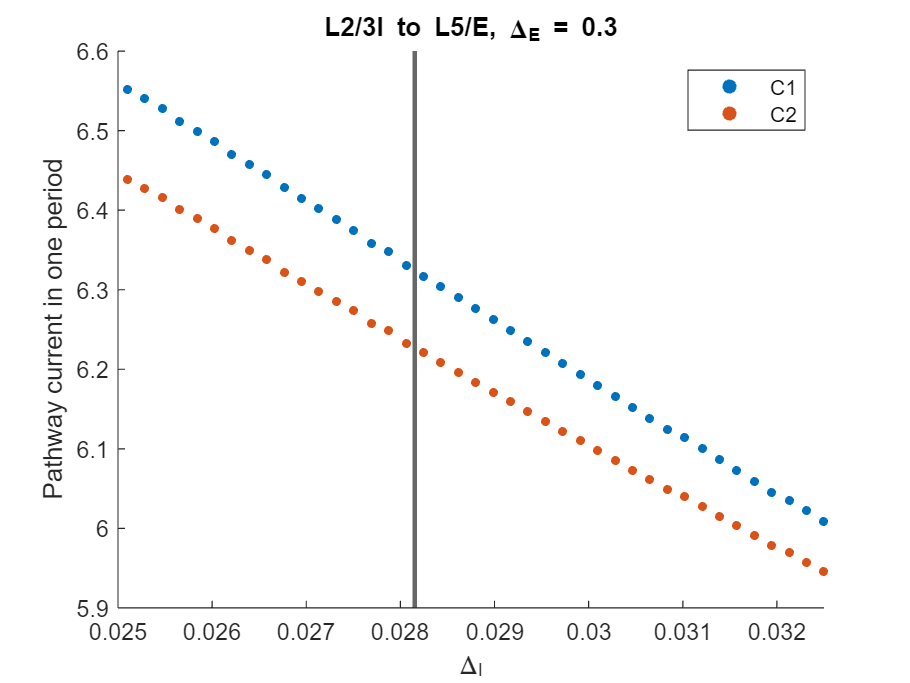

load lateral\lateral_PET_0.3_0.3_0.014_0.0325_Iattn_0.02.mat
startX = 0.014; endX = 0.0325; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

y3 = PETO(:,5,2,4);
y4 = PETO(:,5+8,2+8,4);

figure();
s1 = scatter(x,y3,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,y4,sz,"filled",'MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',2)

xlim([0.025 endX]);
% set(gca, 'YScale', 'log')
title("L2/3I to L5/E, \Delta_{E} = 0.3");
legend([s1 s2], ["C1" "C2"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current in one period");

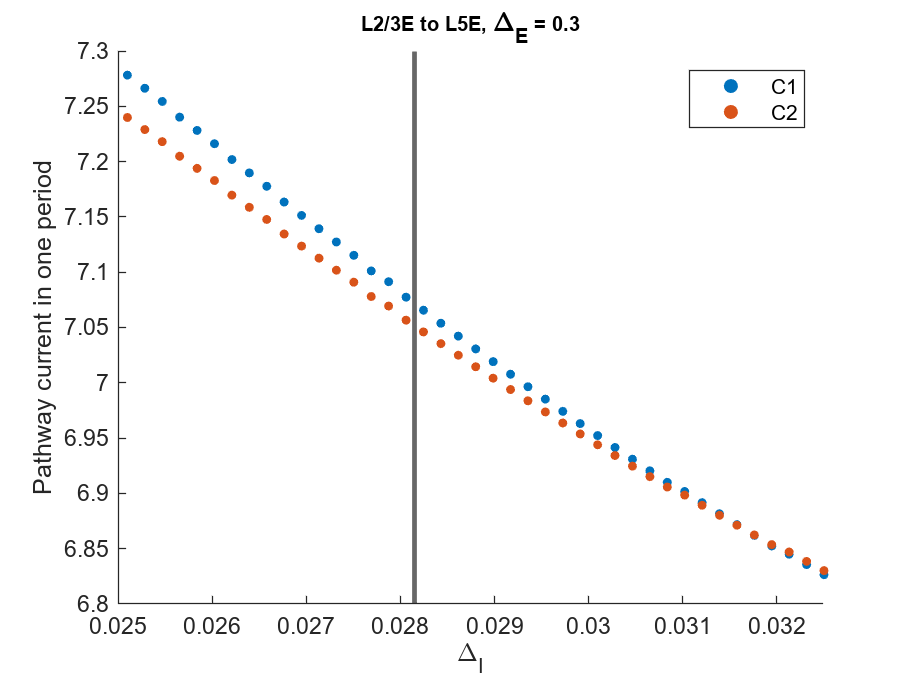

load lateral\lateral_PET_0.3_0.3_0.014_0.0325_Iattn_0.02.mat
startX = 0.014; endX = 0.0325; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

y3 = PETO(:,5,1,4);
y4 = PETO(:,5+8,1+8,4);

figure();
s1 = scatter(x,y3,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,y4,sz,"filled",'MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',2)

xlim([0.025 endX]);
% set(gca, 'YScale', 'log')
title("L2/3E to L5E, \Delta_{E} = 0.3");
legend([s1 s2], ["C1" "C2"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current in one period");

## Recurrent pathway

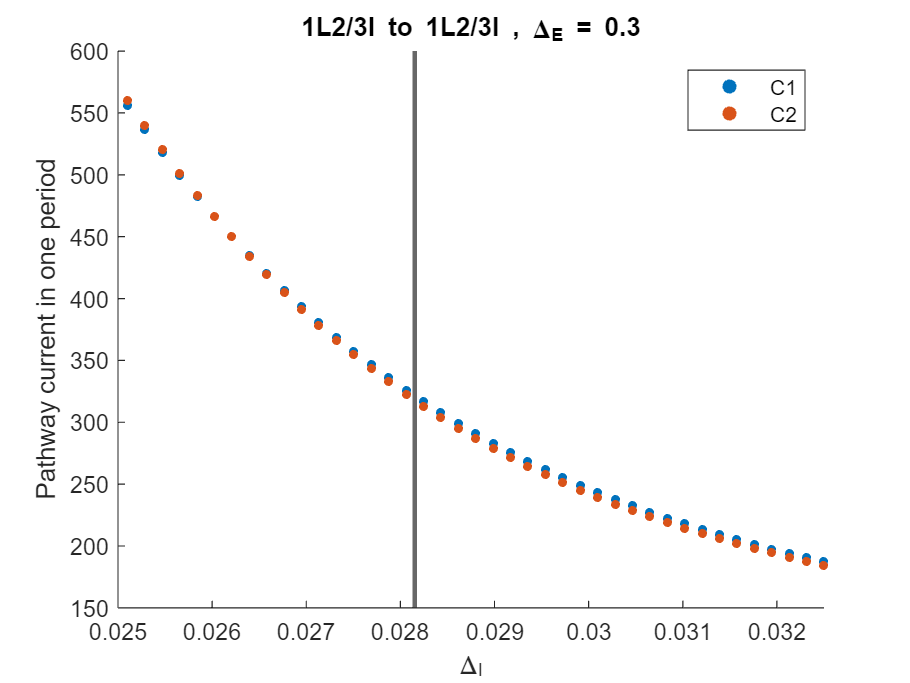

load lateral\lateral_PET_0.3_0.3_0.014_0.0325_Iattn_0.02.mat
pops = {'1L2/3E','1L2/3I','1L4E','1L4I','1L5e','1L5I','1L6E','1L6I', ...
    '2L2/3E','2L2/3I','2L4E','2L4I','2L5E','2L5I','2L6E','2L6I'};
pop1 = 2; pop2 = 2;
startX = 0.014; endX = 0.0325; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

y3 = PETO(:,pop1,pop2,4);
y4 = PETO(:,pop1+8,pop2+8,4);

figure();
s1 = scatter(x,y3,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,y4,sz,"filled",'MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',2)

xlim([0.025 endX]);
% set(gca, 'YScale', 'log')
title(pops(pop1)+" to "+pops(pop2)+" , \Delta_{E} = 0.3");
legend([s1 s2], ["C1" "C2"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current in one period");

## Sum toward pathways

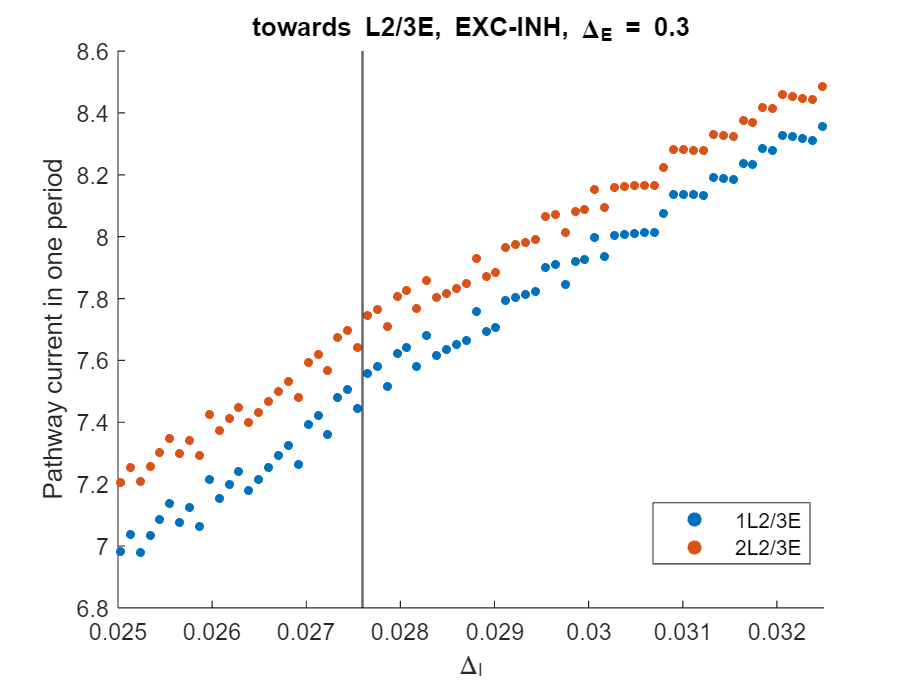

load lateral\lateral_PET_0.3_0.3_0.014_0.035_Iattn_0.02.mat
pops = {'1L2/3E','1L2/3I','1L4E','1L4I','1L5e','1L5I','1L6E','1L6I', ...
    '2L2/3E','2L2/3I','2L4E','2L4I','2L5E','2L5I','2L6E','2L6I'};
pop1 = 1;
startX = 0.014; endX = 0.035; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

exc1 = PETO(:,pop1,1,4) + PETO(:,pop1,3,4) + PETO(:,pop1,5,4) + PETO(:,pop1,7,4);
inh1 = PETO(:,pop1,2,4) + PETO(:,pop1,4,4) + PETO(:,pop1,6,4) + PETO(:,pop1,8,4);

exc2 = PETO(:,pop1+8,1+8,4) + PETO(:,pop1+8,3+8,4) + PETO(:,pop1+8,5+8,4) + PETO(:,pop1+8,7+8,4);
inh2 = PETO(:,pop1+8,2+8,4) + PETO(:,pop1+8,4+8,4) + PETO(:,pop1+8,6+8,4) + PETO(:,pop1+8,8+8,4);

figure();
s1 = scatter(x,exc1-inh1,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
% s2 = scatter(x,inh1,sz,"filled",'MarkerFaceColor',"#0072BD");
s2 = scatter(x,exc2-inh2,sz,"filled",'MarkerFaceColor',"#D95319");
% s3 = scatter(x,exc2,sz,"filled",'MarkerFaceColor',"#D95319");
% s4 = scatter(x,inh2,sz,"filled",'MarkerFaceColor',"#4DBEEE");

xline(x0,'LineWidth',1)

xlim([0.025 0.0325]);
% set(gca, 'YScale', 'log')
title("towards L2/3E, EXC-INH, \Delta_{E} = 0.3");
legend([s1 s2], ["1L2/3E" "2L2/3E"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current in one period");

## From pathways

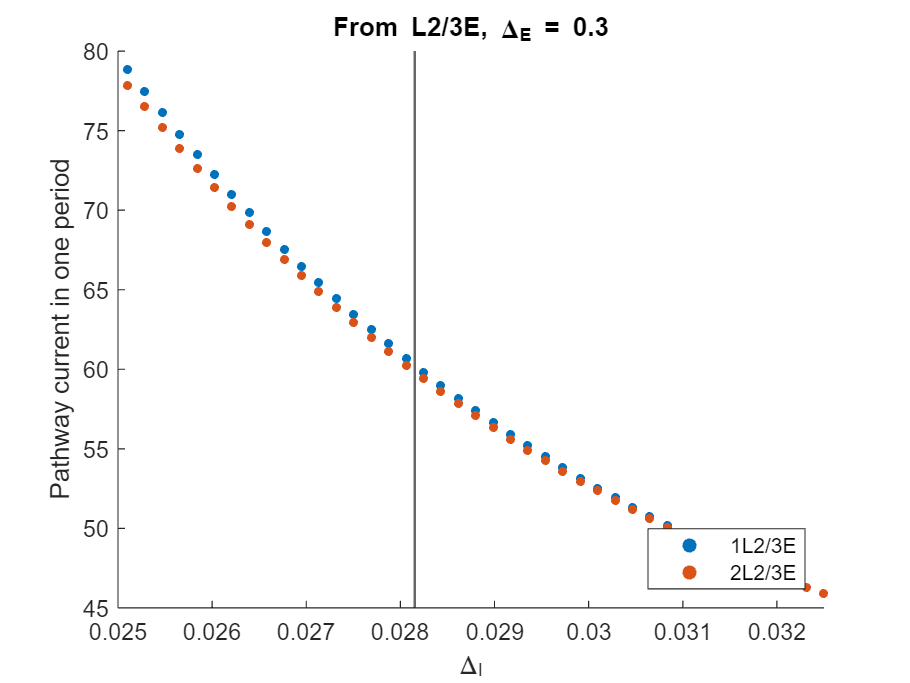

load lateral\lateral_PET_0.3_0.3_0.014_0.0325_Iattn_0.02.mat
pops = {'1L2/3E','1L2/3I','1L4E','1L4I','1L5e','1L5I','1L6E','1L6I', ...
    '2L2/3E','2L2/3I','2L4E','2L4I','2L5E','2L5I','2L6E','2L6I'};
pop1 = 1;
startX = 0.014; endX = 0.0325; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

from1 = sum(PETO(:,:,pop1,4),2);
from2 = sum(PETO(:,:,pop1+8,4),2);

figure();
s1 = scatter(x,from1,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,from2,sz,"filled",'MarkerFaceColor',"#D95319");
% s3 = scatter(x,exc2,sz,"filled",'MarkerFaceColor',"#D95319");
% s4 = scatter(x,inh2,sz,"filled",'MarkerFaceColor',"#4DBEEE");

xline(x0,'LineWidth',1);
% xline(0.0325,'LineWidth',1);

xlim([0.025 endX]);
% set(gca, 'YScale', 'log');
title("From L2/3E, \Delta_{E} = 0.3");
legend([s1 s2], ["1L2/3E" "2L2/3E"], "Location", "southeast");
xlabel("\Delta_{I}");
ylabel("Pathway current in one period");

## r: firing rate

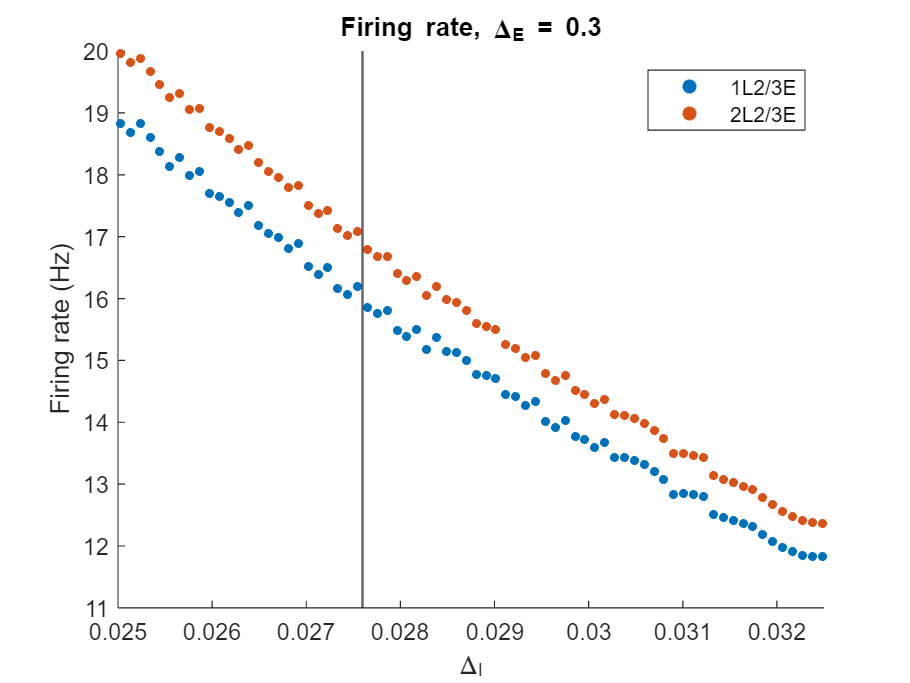

load lateral\lateral_PET_0.3_0.3_0.014_0.035_Iattn_0.02.mat
pops = {'1L2/3E','1L2/3I','1L4E','1L4I','1L5E','1L5I','1L6E','1L6I', ...
    '2L2/3E','2L2/3I','2L4E','2L4I','2L5E','2L5I','2L6E','2L6I'};
startX = 0.014; endX = 0.035; sz = 15; pop = 1;
x = linspace(startX,endX,size(PETO,1));
figure();

y1 = finalR(:,pop,4)*1000;
y2 = finalR(:,pop+8,4)*1000;

s1 = scatter(x,y1,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,y2,sz,"filled",'MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',1);
% xline(0.0325,'LineWidth',1);

xlim([0.025 0.0325]);
title("Firing rate, \Delta_{E} = 0.3");
legend([s1 s2], ["1L2/3E" "2L2/3E"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Firing rate (Hz)");

## Frequency of Gamma wave

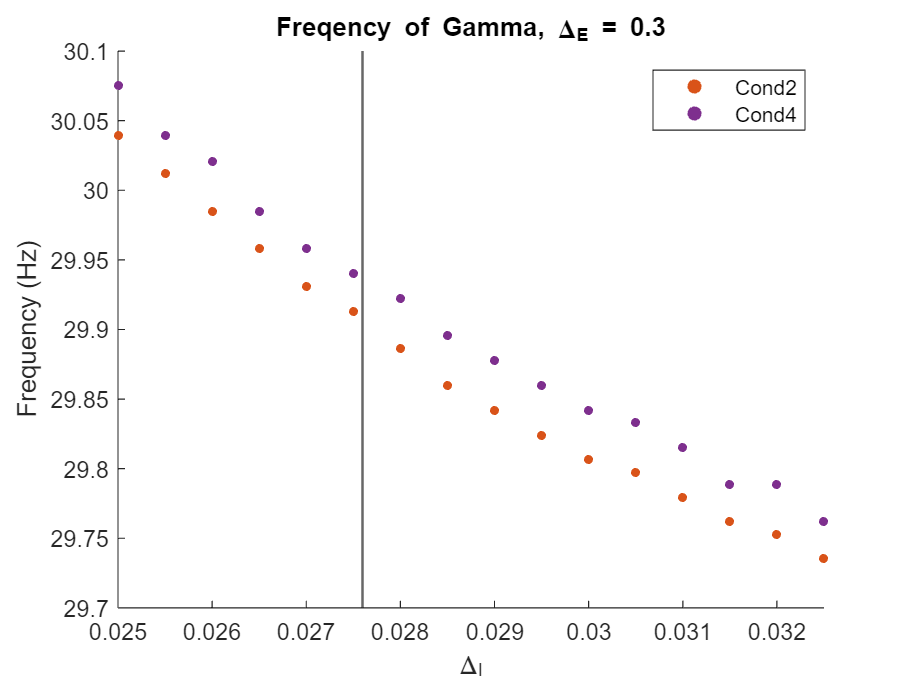

load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
sz = 15;
y2 = gammaSheet(28:65,60,2);
y4 = gammaSheet(28:65,60,4);
x = linspace(0.014,0.0325,65-28+1);
figure();
s2 = scatter(x,y2,sz,"filled",'MarkerFaceColor','#D95319');
hold on;
s4 = scatter(x,y4,sz,"filled",'MarkerFaceColor','#7E2F8E');
xline(x0,'LineWidth',1);
title("Freqency of Gamma, \Delta_{E} = 0.3");
xlim([0.025 0.0325]);
xlabel("\Delta_{I}");
ylabel("Frequency (Hz)");
legend([s2 s4],["Cond2" "Cond4"]);

## \Delta_{E} = 0.2

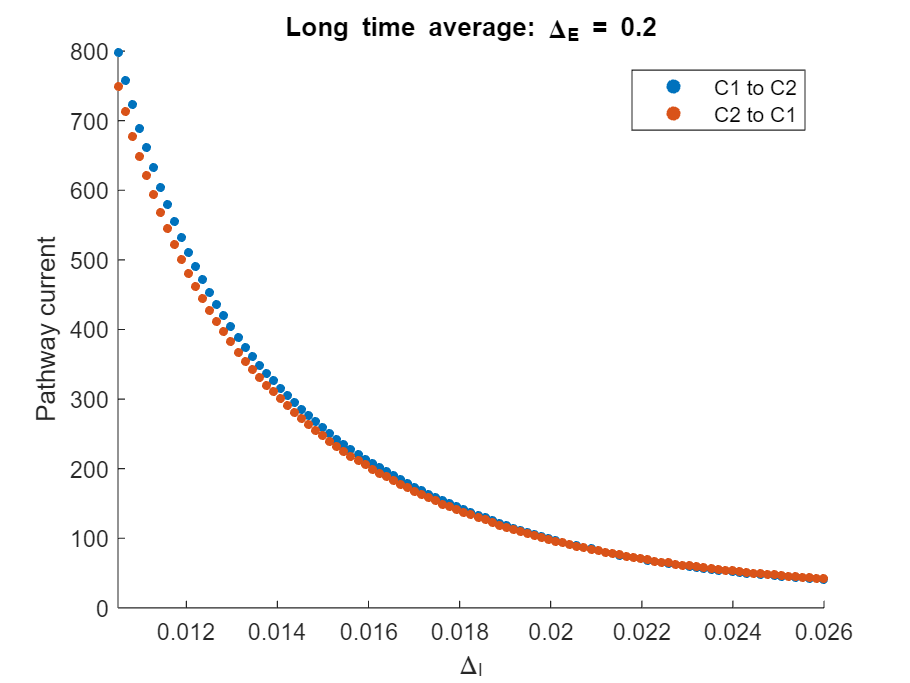

load lateral\lateral_PET_0.2_0.2_0.0105_0.026_Iattn_0.02.mat
startX = 0.0105; endX = 0.026; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETA(:,10,1,4);
y2 = PETA(:,2,9,4);

figure();
s1 = scatter(x,y1,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,y2,sz,"filled",'MarkerFaceColor',"#D95319");
xlim([0.02 endX]);
% set(gca, 'YScale', 'log')
title("Long time average: \Delta_{E} = 0.2");
legend([s1 s2], ["C1 to C2" "C2 to C1"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current");

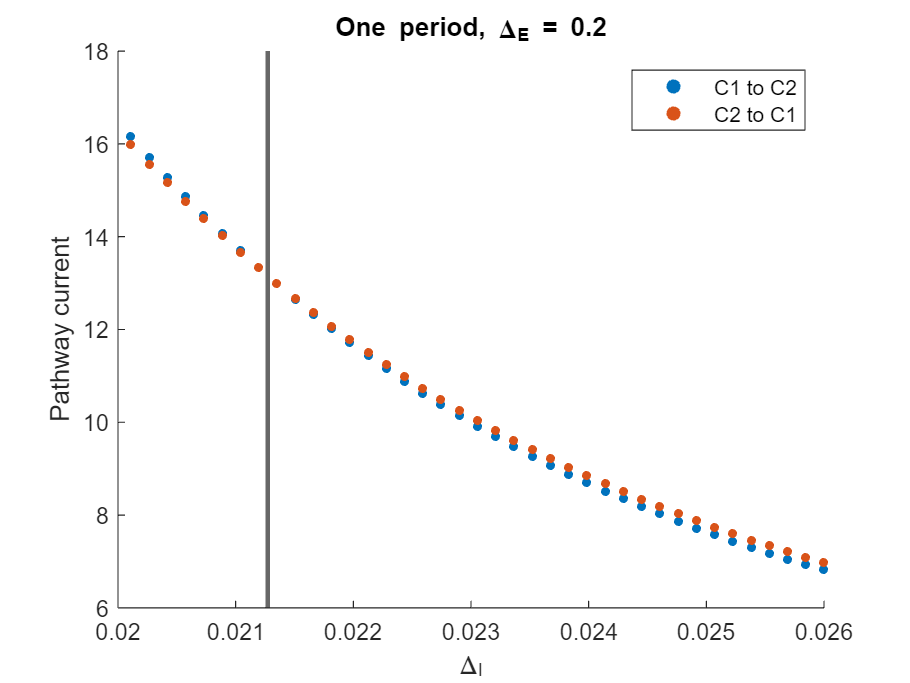

load lateral\lateral_PET_0.2_0.2_0.0105_0.026_Iattn_0.02.mat
startX = 0.0105; endX = 0.026; sz = 15;
x = linspace(startX,endX,size(PETA,1));
y1 = PETO(:,10,1,4);
y2 = PETO(:,2,9,4);

% find zero point
z = y1 - y2; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1,sz,"filled",'MarkerFaceColor',"#0072BD");
hold on
s2 = scatter(x,y2,sz,"filled",'MarkerFaceColor',"#D95319");
xline(x0,'LineWidth',2)

xlim([0.02 endX]);
% set(gca, 'YScale', 'log')
title("One period, \Delta_{E} = 0.2");
legend([s1 s2], ["C1 to C2" "C2 to C1"], "Location", "northeast");
xlabel("\Delta_{I}");
ylabel("Pathway current");

## modify data

% load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
% 
% tmp = ratioSheet(:,:,1);
% ratioSheet = tmp;
% 
% filename = append('lateral_',num2str(Delta_e_start),'_',num2str(Delta_e_end),'_',...
%     num2str(Delta_i_start),'_',num2str(Delta_i_end), '_Iattn_', num2str(Iattn), '.mat');
% save(filename,'lateralSheet','orderSheet','gammaSheet','betaSheet','ratioSheet','osciSheet'); 